# **PART 5: Trajectory generation and control**

clear all
clc

# Exercise 5.1: quintic splines

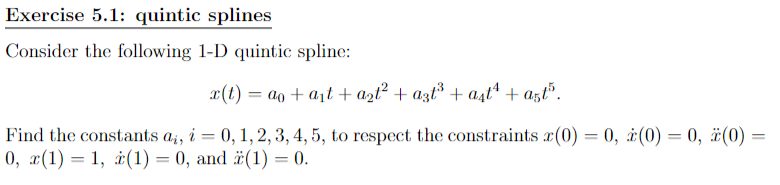

syms t a0 a1 a2 a3 a4 a5 
n=5;
x_t=a0+a1*t+a2*t^2+a3*t^3+a4*t^4+a5*t^5;
x_0=subs(x_t,t,0); %x_0=0
a_0=0;

x_0_dot=diff(x_t);
x_0_dot=subs(x_0_dot,t,0); %x_0_dot=0
a_1=0;

x_0_ddot=diff(diff(x_t));
x_0_ddot=subs(x_0_ddot,t,0); %x_0_ddot=0
a_2=0;

x_1=subs(x_t,t,1) %x_1=1

$$x\_1 = a_{0}+a_{1}+a_{2}+a_{3}+a_{4}+a_{5}$$

x_1=subs(x_1,[a0 a1 a2 a3 a4 a5],[a_0 a_1 a_2 a3 a4 a5])

$$x\_1 = a_{3}+a_{4}+a_{5}$$


x_1_dot=diff(x_t); %x_1_dot
x_1_dot=subs(x_1_dot,t,1)

$$x\_1\_dot = a_{1}+2\,a_{2}+3\,a_{3}+4\,a_{4}+5\,a_{5}$$

x_1_dot=subs(x_1_dot,[a0 a1 a2 a3 a4 a5],[a_0 a_1 a_2 a3 a4 a5])

$$x\_1\_dot = 3\,a_{3}+4\,a_{4}+5\,a_{5}$$


x_1_ddot=diff(diff(x_t)); %x_1_ddot
x_1_ddot=subs(x_1_ddot,t,1)

$$x\_1\_ddot = 2\,a_{2}+6\,a_{3}+12\,a_{4}+20\,a_{5}$$

x_1_ddot=subs(x_1_ddot,[a0 a1 a2 a3 a4 a5],[a_0 a_1 a_2 a3 a4 a5])

$$x\_1\_ddot = 6\,a_{3}+12\,a_{4}+20\,a_{5}$$


x_1_solve=solve([x_1==1, x_1_dot==0, x_1_ddot==0],[a3, a4, a5])

x_1_solve = struct with fields:
    a3: 10
    a4: -15
    a5: 6



x_t_last=subs(x_t,[a0 a1 a2 a3 a4 a5],[a_0 a_1 a_2 x_1_solve.a3 x_1_solve.a4 x_1_solve.a5])

$$x\_t\_last = 6\,t^{5}-15\,t^{4}+10\,t^{3}$$

# Exercise 5.2: B-splines

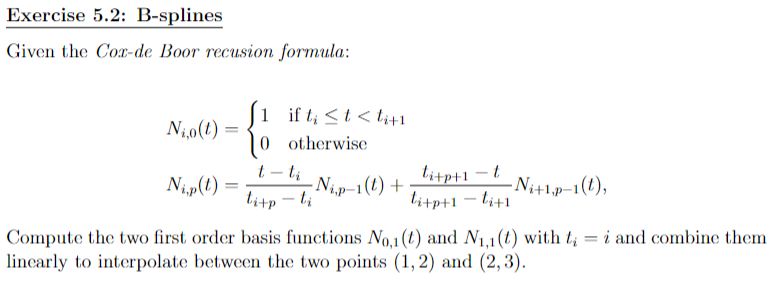

N_i_0=[1;0];
syms N_i_p1 t t_i_p t_i t_i_p1 t_i1 N_i1_p1
%N_i_p1     %Ni,p−1(t)
%t          %t
%t_i        %ti
%t_i_p      %ti+p 
%t_i        %ti

%N_i1_p1    %Ni+1,p−1(t)
%t_i_p1     %ti+p+1
%t          %t
%t_i_p1     %ti+p+1
%t_i1       %ti+1

N_i_p=(((t-t_i)/(t_i_p-t_i))*N_i_p1)+(((t_i_p1-t)/(t_i_p1-t_i1))*N_i1_p1)

$$N\_i\_p = \frac{N_{\mathrm{i1},\mathrm{p1}}\,\left(t-t_{i,\mathrm{p1}}\right)}{t_{\mathrm{i1}}-t_{i,\mathrm{p1}}}-\frac{N_{i,\mathrm{p1}}\,\left(t-t_{i}\right)}{t_{i}-t_{i,p}}$$

% dont on paper
%

# Exercise 5.3: computation of a DCM

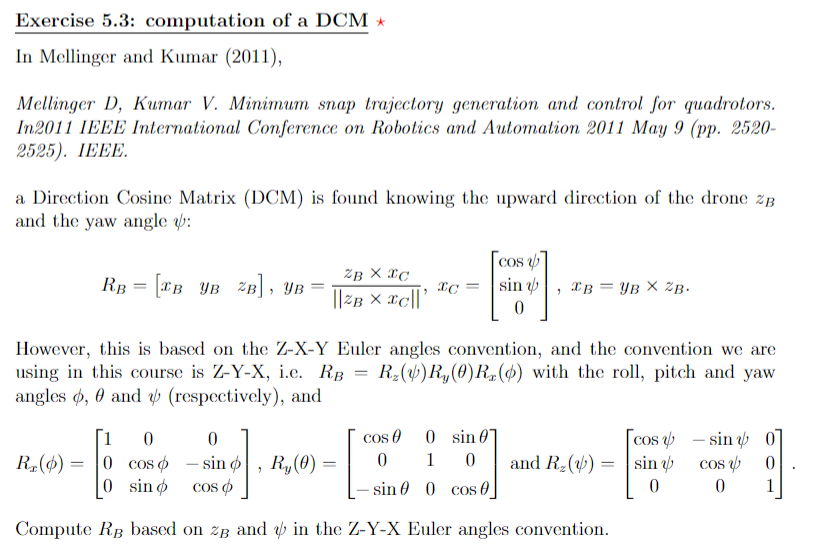

syms x_b y_b z_b psi theta phi zb_x zb_y zb_z a z_b
x_c=[cos(psi); sin(psi); 0];
z_b=[zb_x; zb_y; zb_z];
y_b=cross(z_b,x_c)/norm(cross(z_b,x_c))

$$y\_b = \begin{array}{l} \left(\begin{array}{c} -\frac{{\mathrm{zb}}_{z}\,\sin\left(\psi \right)}{\sigma_{1}}\\ \frac{{\mathrm{zb}}_{z}\,\cos\left(\psi \right)}{\sigma_{1}}\\ -\frac{{\mathrm{zb}}_{y}\,\cos\left(\psi \right)-{\mathrm{zb}}_{x}\,\sin\left(\psi \right)}{\sigma_{1}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sqrt{{\left|{\mathrm{zb}}_{z}\,\cos\left(\psi \right)\right|}^{2}+{\left|{\mathrm{zb}}_{z}\,\sin\left(\psi \right)\right|}^{2}+{\left|{\mathrm{zb}}_{y}\,\cos\left(\psi \right)-{\mathrm{zb}}_{x}\,\sin\left(\psi \right)\right|}^{2}} \end{array}$$

x_b=cross(y_b,z_b);

R_b=[x_b y_b z_b]

$$R\_b = \begin{array}{l} \left(\begin{array}{ccc} \frac{{{\mathrm{zb}}_{z}}^{2}\,\cos\left(\psi \right)}{\sigma_{1}}+\frac{{\mathrm{zb}}_{y}\,\sigma_{2}}{\sigma_{1}} & -\frac{{\mathrm{zb}}_{z}\,\sin\left(\psi \right)}{\sigma_{1}} & {\mathrm{zb}}_{x}\\ \frac{{{\mathrm{zb}}_{z}}^{2}\,\sin\left(\psi \right)}{\sigma_{1}}-\frac{{\mathrm{zb}}_{x}\,\sigma_{2}}{\sigma_{1}} & \frac{{\mathrm{zb}}_{z}\,\cos\left(\psi \right)}{\sigma_{1}} & {\mathrm{zb}}_{y}\\ -\frac{{\mathrm{zb}}_{x}\,{\mathrm{zb}}_{z}\,\cos\left(\psi \right)}{\sigma_{1}}-\frac{{\mathrm{zb}}_{y}\,{\mathrm{zb}}_{z}\,\sin\left(\psi \right)}{\sigma_{1}} & -\frac{\sigma_{2}}{\sigma_{1}} & {\mathrm{zb}}_{z} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sqrt{{\left|{\mathrm{zb}}_{z}\,\cos\left(\psi \right)\right|}^{2}+{\left|{\mathrm{zb}}_{z}\,\sin\left(\psi \right)\right|}^{2}+{\left|\sigma_{2}\right|}^{2}}\\ \sigma_{2}={\mathrm{zb}}_{y}\,\cos\left(\psi \right)-{\mathrm{zb}}_{x}\,\sin\left(\psi \right) \end{array}$$


R=rotz(a)*roty(theta)*rotx(phi)

$$R = \left(\begin{array}{ccc} \cos\left(a\right)\,\cos\left(\theta \right) & \cos\left(a\right)\,\sin\left(\varphi \right)\,\sin\left(\theta \right)-\cos\left(\varphi \right)\,\sin\left(a\right) & \sin\left(a\right)\,\sin\left(\varphi \right)+\cos\left(a\right)\,\cos\left(\varphi \right)\,\sin\left(\theta \right)\\ \sin\left(a\right)\,\cos\left(\theta \right) & \cos\left(a\right)\,\cos\left(\varphi \right)+\sin\left(a\right)\,\sin\left(\varphi \right)\,\sin\left(\theta \right) & \cos\left(\varphi \right)\,\sin\left(a\right)\,\sin\left(\theta \right)-\cos\left(a\right)\,\sin\left(\varphi \right)\\ -\sin\left(\theta \right) & \cos\left(\theta \right)\,\sin\left(\varphi \right) & \cos\left(\varphi \right)\,\cos\left(\theta \right) \end{array}\right)$$



a=atan(C23/C13)

Unrecognized function or variable 'C23'.

theta=-asin(Rzx)
phi=atan(Ryx/Rxx)


    [0     0;
     1     0;
     2     0;
     3     0;
     4     0;
     5     0;
     6     0;
     7     0;
     8     0;
     9     0;
     9     1;
     9     2;
     9     3;
     9     4;
     9     5;
     8     5;
     7     5;
     7     6;
     7     7;
     6     7;
     5     7;
     5     6;
     5     5;
     4     5;
     3     5]

ans =      0     0
     1     0
     2     0
     3     0
     4     0
     5     0
     6     0
     7     0
     8     0
     9     0


function [rotmtx] = rotx(angle)
% return the rotation matrix around x axis
% angle: degree
rotmtx = [1, 0, 0; 0, cos(angle), -sin(angle); 0, sin(angle), cos(angle)];
end

function [rotmtx] = roty(angle)
% return the rotation matrix around x axis
% angle: degree
rotmtx = [cos(angle), 0, sin(angle); 0, 1, 0; -sin(angle), 0, cos(angle)];
end

function [rotmtx] = rotz(angle)
% return the rotation matrix around x axis
% angle: degree
rotmtx = [cos(angle), -sin(angle), 0; sin(angle), cos(angle), 0; 0, 0, 1];
end














